%   "Seismic Signal Analyzer"

% Specify the path to our Excel file (data file)
excelFilePath = 'D:\DSP final project\database.csv';

% Load data from the Excel file as a table
earthquakeTable = readtable(excelFilePath);


% Display the first few rows of the data
disp('First few rows of the earthquake data:');

First few rows of the earthquake data:


head(earthquakeTable)

ans = 8×21 table
       Date         Time      Latitude    Longitude        Type        Depth    DepthError    DepthSeismicStations    Magnitude    MagnitudeType    MagnitudeError    MagnitudeSeismicStations    AzimuthalGap    HorizontalDistance    HorizontalError    RootMeanSquare          ID           Source     LocationSource    MagnitudeSource      Status   
    __________    ________    ________    _________    ____________    _____    __________    ____________________    _________


% Analyzing data
% Display summary statistics of the data
disp('Summary statistics of the earthquake data:');

Summary statistics of the earthquake data:


summary(earthquakeTable)


Variables:

    Date: 23412×1 datetime

        Values:

            Min            01/02/1965 
            Median         11/30/1993 
            Max            12/30/2016 
            NumMissing     3          

    Time: 23412×1 duration

        Values:

            Min            00:00:03 
            Median         11:54:56 
            Max            23:59:58 
            NumMissing     3        

    Latitude: 23412×1 double

        Values:

            Min         -77.08  
            Median     -3.5685  
            Max         86.005  

    Longitude: 23412×1 double

        Values:

            Min           -180   
            Median      103.98   
            Max            180   

    Type: 23412×1 cell array of character vectors

    Depth: 23412×1 double

        Values:

            Min        -1.1  
            Median       33  
            Max         700  

    <


% Perform statistical operations on data
meanMagnitude = mean(earthquakeTable.Magnitude);
meanMagnitude

meanMagnitude = 5.8825

maxDepth = max(earthquakeTable.Depth);
maxDepth

maxDepth = 700


seismicMoment = 10.^(1.5 * (earthquakeTable.Magnitude + 6.06));
seismicMoment

seismicMoment = 	1.0e+22 *

    0.0001
    0.0001
    0.0002
    0.0001
    0.0001
    0.0014
    0.0001
    0.0001
    0.0001
    0.0001


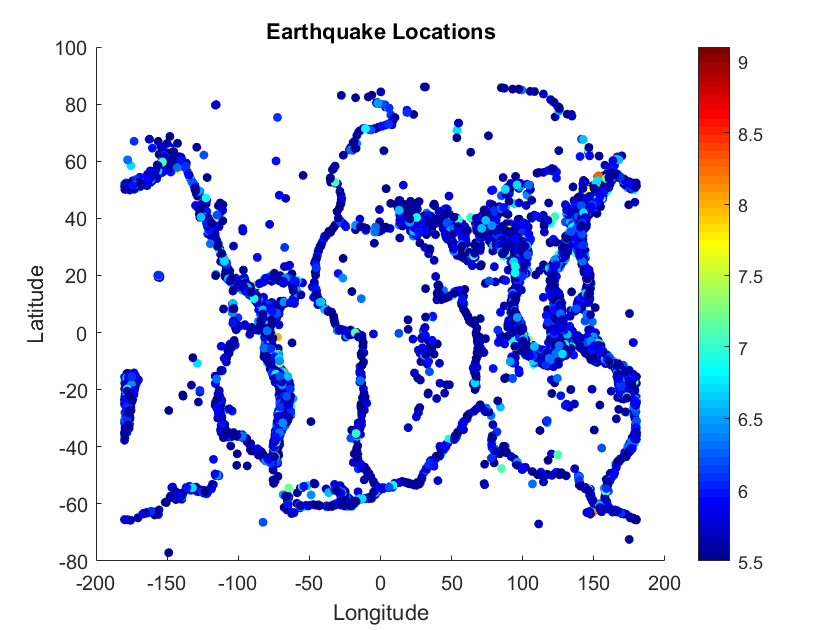


% Scatter plot of earthquake locations
figure;
scatter(earthquakeTable.Longitude, earthquakeTable.Latitude, 20, earthquakeTable.Magnitude, 'filled');
title('Earthquake Locations');
xlabel('Longitude');
ylabel('Latitude');
colorbar;
colormap('jet');

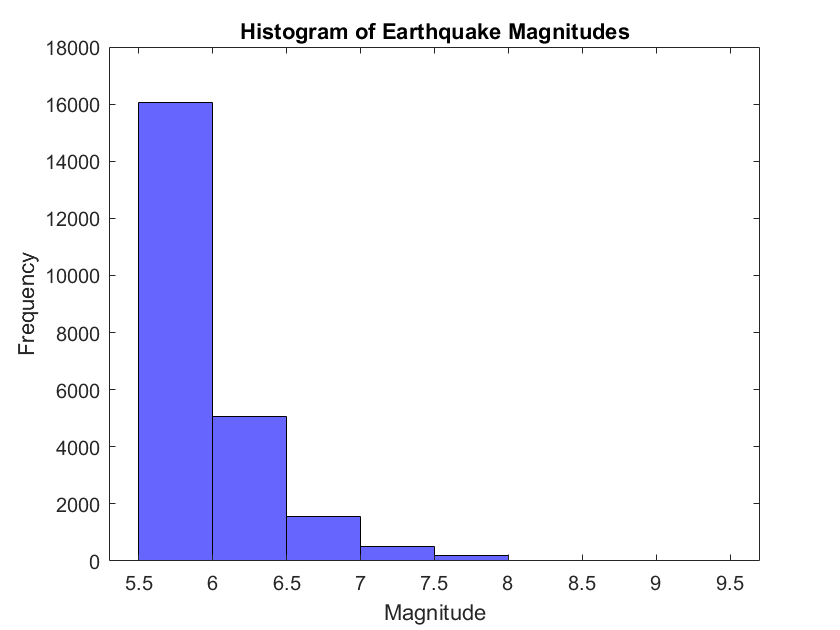


% Histogram of earthquake magnitudes
figure;
histogram(earthquakeTable.Magnitude, 'BinWidth', 0.5, 'FaceColor', 'blue', 'EdgeColor', 'black');
title('Histogram of Earthquake Magnitudes');
xlabel('Magnitude');
ylabel('Frequency');

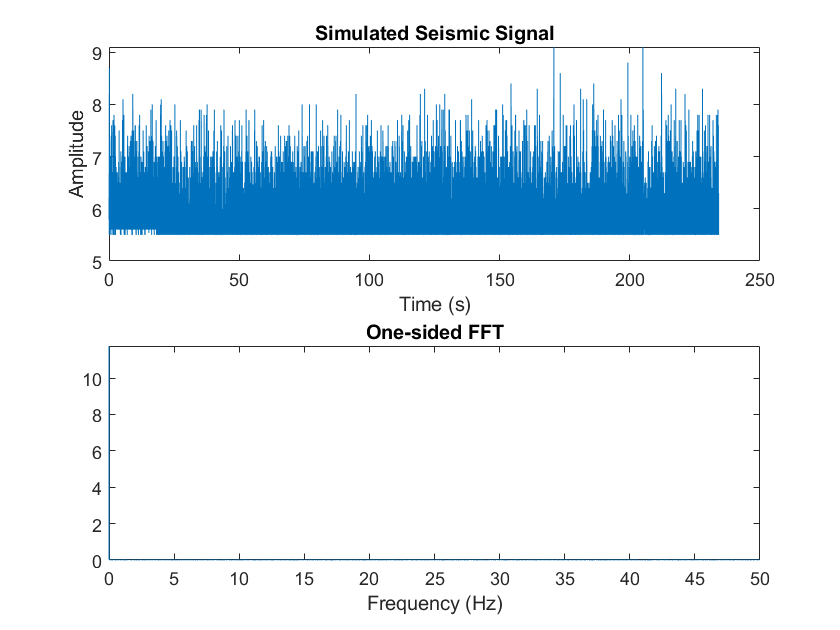


% Extract seismic signal from the data
seismicSignal = earthquakeTable.Magnitude;

% Fourier analysis of the seismic signal
timeStep = 0.01;  
Fs = 1 / timeStep; % Sampling frequency
N = numel(seismicSignal); % Number of data points
frequencies = Fs * (0:(N/2)) / N; % Frequency axis for plotting

% Perform Fourier Transform
seismicFFT = fft(seismicSignal);
magnitudeFFT = (2/N) * abs(seismicFFT(1:N/2+1));

% Plot the seismic signal and its FFT graph
figure;

subplot(2,1,1);
plot(0:timeStep:(numel(seismicSignal)-1)*timeStep, seismicSignal);
title('Simulated Seismic Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(frequencies, magnitudeFFT);
title('One-sided FFT');
xlabel('Frequency (Hz)');


% Normalization of FFT
magnitudeFFT = (2/N) * abs(seismicFFT(1:N/2+1));
magnitudeFFT

magnitudeFFT =    11.7651
    0.0265
    0.0371
    0.0300
    0.0341
    0.0203
    0.0132
    0.0100
    0.0073
    0.0075
